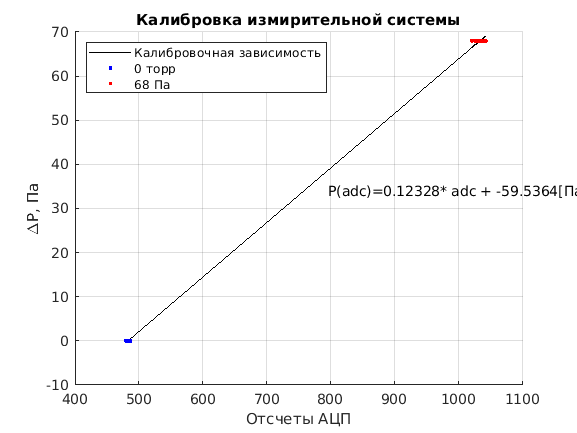

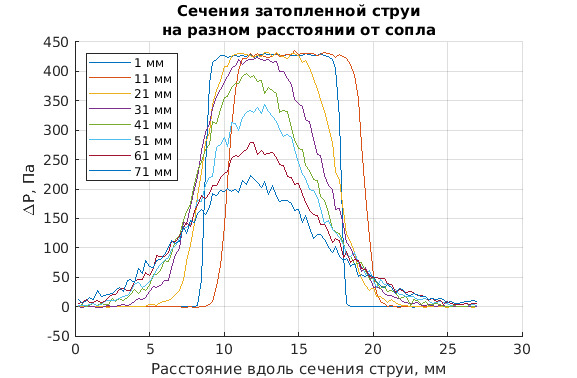

callib = load('calib.dat');
callibr_zero = load("calibzero.dat");
mm01 = load ("01mm.dat");
mm11 = load("11mm.dat");
mm21 = load("21mm.dat");
mm31 = load("31mm.dat");
mm41 = load("41mm.dat");
mm51 = load("51mm.dat");
mm61 = load("61mm.dat");
mm71 = load("71mm.dat");
adc_1 = callib (:, 2);
adc_2 = callibr_zero (:, 2);
p1 = ones(length(adc_1),1)*68;
p2 = ones(length(adc_2),1)*0;
Adc_c = [adc_1; adc_2];
P_c = [p1; p2];
c = polyfit(Adc_c, P_c, 1);
callibrFigure = figure ('Name','Калибровка', "NumberTitle","off");
hold all;
plot(Adc_c, polyval(c, Adc_c),'k-');
plot(adc_2, p2, 'b.');
plot(adc_1, p1, 'r.');
grid on;
xlabel('Отсчеты АЦП');
ylabel('\DeltaP, Па');
legend('Калибровочная зависимость','0 торр','68 Па', 'Location',"northwest");
title('Калибровка измирительной системы');
text(mean(Adc_c)*1.05, mean(P_c),['P(adc)=', num2str(c(1)), '* adc + ', num2str(c(2)), '[Па]']);
%%set(gcf, "Visible", "on")
dx = 0.25;
x = mm01(:, 1)'*0.25;
p01 = polyval(c , mm01(:,2));
p11 = polyval(c , mm11(:,2));
p21 = polyval(c , mm21(:,2));
p31 = polyval(c , mm31(:,2));
p41 = polyval(c , mm41(:,2));
p51 = polyval(c , mm51(:,2));
p61 = polyval(c , mm61(:,2));
p71 = polyval(c , mm71(:,2));
pressure = [p01, p11, p21, p31, p41, p51, p61, p71];
zNames = {'1 мм'; '11 мм'; '21 мм'; '31 мм'; '41 мм'; '51 мм'; '61 мм';'71 мм'};
z = [1, 11, 21,31,41,51, 61, 71];
f2 = figure ('Name','Калибровка      ', "NumberTitle","off"); 
hold on;
grid on; 
title({'Сечения затопленной струи', 'на разном расстоянии от сопла'});
xlabel('Расстояние вдоль сечения струи, мм');
ylabel('\DeltaP, Па');
for i = 1:size (pressure, 2)
    plot(x, pressure(:, i), "DisplayName", zNames{i});
end
legend('Location','northwest');
saveas(f2, 'pressure.png');
set(gcf, "Visible", "on");
f3 = figure('Name','Калибровка      ', "NumberTitle","off");
hold on ;
grid on;
title({'Центрированные сечения затопленной струи', 'на разном расстоянии от сопла'});
xlabel({'Расстояние вдоль сечения струи,','относительно её центра, мм'});
ylabel('\DeltaP, Па');
xCentred = zeros(size(pressure));
offset = 50;
for i = 1:size(pressure, 2)
    right = x(find(pressure(:, i) > offset, 1, 'last'));
    left = x(find(pressure(:, i) > offset, 1));
    center = left + (right - left)/2 ;
    xCentred(:, i) = x - center;
    plot(xCentred(:, i), pressure(:,i), 'DisplayName', zNames{i});
end
legend('Location','northwest');
saveas(f3, 'centered_pressure.png');

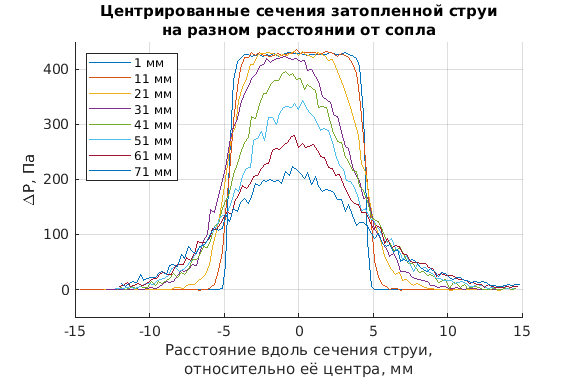

set(gcf, "Visible", "on");
hold off;

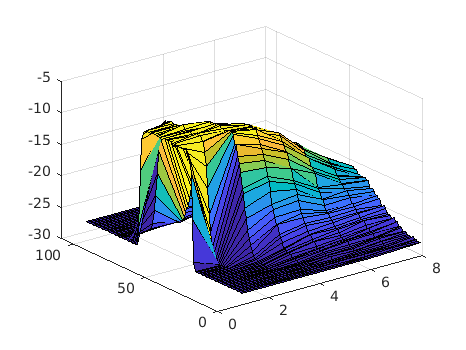

U_01 = -sqrt(2*abs(p01-mean(adc_2))/1.2);
U_11 = -sqrt(2*abs(p11-mean(adc_2))/1.2);
U_21 = -sqrt(2*abs(p21-mean(adc_2))/1.2);
U_31 = -sqrt(2*abs(p31-mean(adc_2))/1.2);
U_41 = -sqrt(2*abs(p41-mean(adc_2))/1.2);
U_51 = -sqrt(2*abs(p51-mean(adc_2))/1.2);
U_61 = -sqrt(2*abs(p61-mean(adc_2))/1.2);
U_71 = -sqrt(2*abs(p71-mean(adc_2))/1.2);
U_z = [U_01, U_11, U_21, U_31, U_41, U_51, U_61, U_71];
f5 = figure();
surf(U_z);
set(gcf, "Visible", "on");